Wp1 = 10/360;
Ws1 = 20/360;
Rp1= 1;
Rs1 = 40;
[n1,Wp1] = cheb1ord(Wp1,Ws1,Rp1,Rs1)

n1 = 5

Wp1 = 0.0278

[b1,c1] = cheby1(n1,Rp1,Wp1);
sys1 = tf(b1,c1,(1/720))

sys1 =
 
  1.866e-08 z^5 + 9.331e-08 z^4 + 1.866e-07 z^3 + 1.866e-07 z^2 + 9.331e-08 z + 1.866e-08
  ---------------------------------------------------------------------------------------
                z^5 - 4.909 z^4 + 9.649 z^3 - 9.492 z^2 + 4.674 z - 0.9215
 
Sample time: 0.0013889 seconds
Discrete-time transfer function.



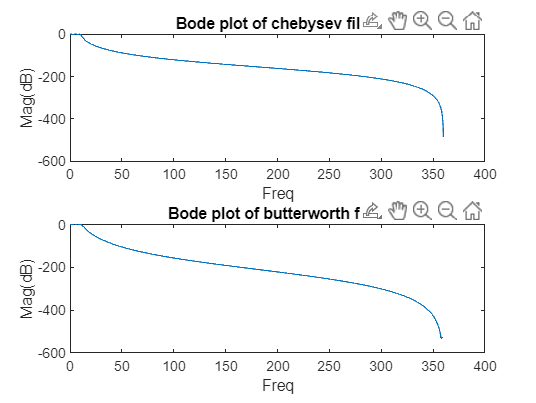

subplot(2,1,1);
[Mag1,Phase1] = bode(sys1,2*pi*w);
plot(w,db(squeeze(Mag1)))
xlabel('Freq')
ylabel('Mag(dB)')
title('Bode plot of chebysev filter');
subplot(2,1,2);
[Mag,Phase] = bode(sys,2*pi*w);
plot(w,db(squeeze(Mag)))
xlabel('Freq')
ylabel('Mag(dB)')
title('Bode plot of butterworth filter');